# Detailed analysis of the 1DOF cell model

%%
clear all; close all; clc;
addpath("Functions and Scripts\");
addpath("1DOF\");
set_env;
strpstrain = "PSTRAIN";
strpstress = "PSTRESS";
%

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum
epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)
% 
% % Strains: eps1 along the polymer, eps3 thickness strain of the polymer
syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)

## Equations

syms eps1 eps2 eps3 s1 s2 s3


% Equations ---------------------------------------------------------
eqstrain = [
eps1 == 1 / Y_p * (s1 - nu * (s2 + s3)),...
eps2 == 1 / Y_p * (s2 - nu * (s1 + s3)),...
eps3 == 1 / Y_p * (s3 - nu * (s1 + s2))
]

$$eqstrain = \left(\begin{array}{ccc} {\mathrm{eps}}_{1}=\frac{s_{1}-\nu \,\left(s_{2}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{2}=\frac{s_{2}-\nu \,\left(s_{1}+s_{3}\right)}{Y_{p}} & {\mathrm{eps}}_{3}=\frac{s_{3}-\nu \,\left(s_{1}+s_{2}\right)}{Y_{p}} \end{array}\right)$$

pstrain_sol = solve(subs(eqstrain, {eps2, s3}, {0,0}), [s1,s2,eps3]) % Plane strain

pstrain_sol = struct with fields:
      s1: -(Y_p*eps1)/(nu^2 - 1)
      s2: -(Y_p*eps1*nu)/(nu^2 - 1)
    eps3: (eps1*nu)/(nu - 1)


pstress_sol = solve(subs(eqstrain, {s2, s3}, {0,0}), [s1,eps2,eps3]) % Plane stress

pstress_sol = struct with fields:
      s1: Y_p*eps1
    eps2: -eps1*nu
    eps3: -eps1*nu


% Geometry ------------------------------

dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f; 

[pstrain, pstress, nostrain] = compute_geometry1(t_f)

pstrain = struct with fields:
      l: l_0*(epsilon_1(x) + 1)
    t_p: tp_0*(epsilon_3(x) + 1)
      w: w_0
      A: l_0*w_0*(epsilon_1(x) + 1)
     dC: [1×1 symfun]
      C: [1×1 symfun]


pstress = struct with fields:
      l: l_0*(epsilon_1(x) + 1)
    t_p: tp_0*(epsilon_3(x) + 1)
      w: w_0*(epsilon_2(x) + 1)
      A: l_0*w_0*(epsilon_1(x) + 1)*(epsilon_2(x) + 1)
     dC: [1×1 symfun]
      C: [1×1 symfun]


nostrain = struct with fields:
      l: l_0
    t_p: tp_0
      w: w_0
      A: l_0*w_0
     dC: [1×1 symfun]
      C: [1×1 symfun]


pstrain.C = sstrain1(pstrain.C, strpstrain);
pstress.C = sstrain1(pstress.C, strpstress);

% Range limit
x_min = sdata1(tf_0);
x_max = sdata1(rhs(isolate(sstrain1(epsilon_1(x)) == epsilon1_max, x)))

$$x\_max = \frac{\sqrt{41}}{400}+\frac{1}{10000}$$

x_minmax = [double(x_min) double(x_max)];

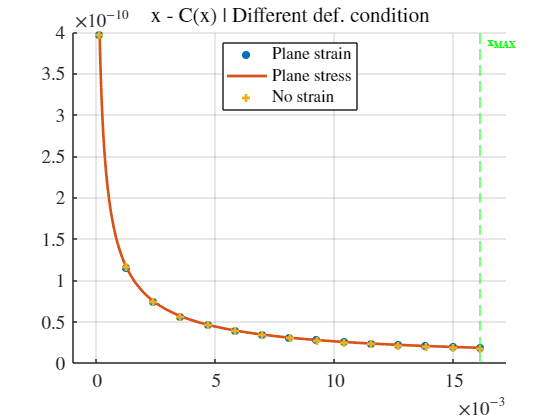

% C(x): Plane strain - Plane stress - No strain
myfig(1,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstrain.C), x_minmax, '*', 'LineWidth',2, 'DisplayName', 'Plane strain')
fplot(x, sdata1(pstress.C), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, sdata1(nostrain.C), x_minmax, '+', 'LineWidth',2, 'DisplayName', 'No strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Different def. condition")
xlim("padded")

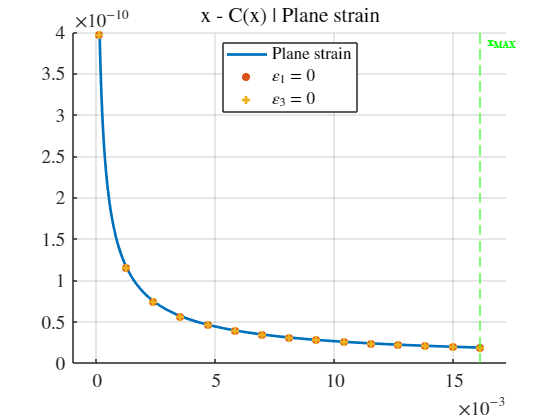

% C(x): Plane strain with epsilon_1 = 0 or epsilon_3 = 0
myfig(2,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstrain.C), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane strain')
fplot(x, sdata1(subs(pstrain.C, epsilon_1, 0)), x_minmax, '*', 'LineWidth',2, 'DisplayName', '$\varepsilon_1 = 0$')
fplot(x, sdata1(subs(pstrain.C, epsilon_3, 0)), x_minmax, '+', 'LineWidth',2, 'DisplayName', '$\varepsilon_3 = 0$')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Plane strain")
xlim("padded")

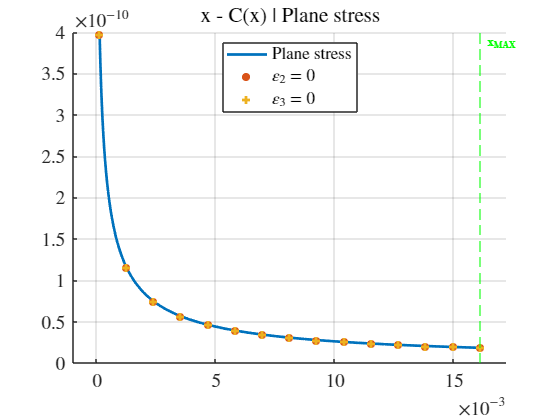

% C(x): Plane strain with epsilon_1 = 0 or epsilon_2 = 0
myfig(3,"x - C(x)"); clf; hold on
fplot(x, sdata1(pstress.C), x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, sdata1(subs(pstress.C, epsilon_2, 0)), x_minmax, '*', 'LineWidth',2, 'DisplayName', '$\varepsilon_2 = 0$')
fplot(x, sdata1(subs(pstress.C, epsilon_3, 0)), x_minmax, '+', 'LineWidth',2, 'DisplayName', '$\varepsilon_3 = 0$')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) | Plane stress")
xlim("padded")

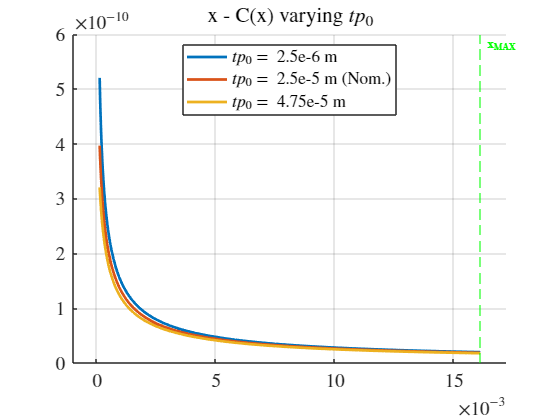

% C(x): Plane strain with different tp_0
tp0_range = sdata1(tp_0) - 0.9*sdata1(tp_0) : 0.9*sdata1(tp_0) : sdata1(tp_0) + 0.9*sdata1(tp_0);
C_tp0 = subs(sdata1(pstrain.C, 'except', tp_0), tp_0, tp0_range);

myfig(4, "x - C(x) varying $tp_0$"); hold on
for i = 1:length(tp0_range)
    if i == 2
        name = strjoin(["$tp_0 =$", string(vpa(tp0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$tp_0 =$", string(vpa(tp0_range(i),4)), "m"]);
    end
    
    fplot(x, pickelem(C_tp0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $tp_0$")
xlim("padded")

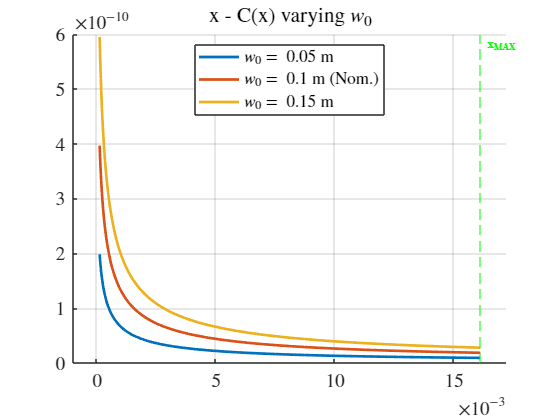

% C(x): Plane strain with different w_0
w0_range = sdata1(w_0) - 0.5*sdata1(w_0) : 0.5*sdata1(w_0) : sdata1(w_0) + 0.5*sdata1(w_0);
C_w0 = subs(sdata1(pstrain.C, 'except', w_0), w_0, w0_range);

myfig(4, "x - C(x) varying $w_0$"); hold on
for i = 1:length(w0_range)
    if i == 2
        name = strjoin(["$w_0 =$", string(vpa(w0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$w_0 =$", string(vpa(w0_range(i),4)), "m"]);
    end
    
    fplot(x, pickelem(C_w0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $w_0$")
xlim("padded")

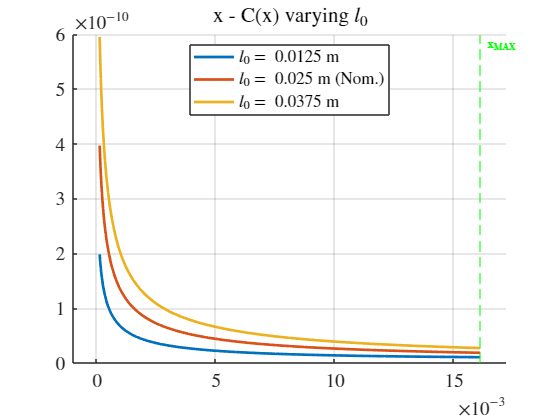

% C(x): Plane strain with different l_0
l0_range = sdata1(l_0) - 0.5*sdata1(l_0) : 0.5*sdata1(l_0) : sdata1(l_0) + 0.5*sdata1(l_0);
C_l0 = subs(sdata1(pstrain.C, 'except', l_0), l_0, l0_range);

myfig(4, "x - C(x) varying $l_0$"); hold on
for i = 1:length(l0_range)
    if i == 2
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m"]);
    end
    
    fplot(x, pickelem(C_l0(x), i), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','north')
title("x - C(x) varying $l_0$")
xlim("padded")

% Vmax(x): Plane stress - Plane strain
tmp = sym2cell(2 * [pstress.t_p, pstrain.t_p] / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f));
[Vmax_pstress, Vmax_pstrain] = deal(tmp{:})

$$Vmax\_pstress = \frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},{\mathrm{EBD}}_{f}\notin \mathbb{R}\vee {\mathrm{EBD}}_{p}\notin \mathbb{R}\vee \epsilon_{f}\notin \mathbb{R}\vee \epsilon_{p}\notin \mathbb{R}\right)}{\epsilon_{p}}$$

$$Vmax\_pstrain = \frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},{\mathrm{EBD}}_{f}\notin \mathbb{R}\vee {\mathrm{EBD}}_{p}\notin \mathbb{R}\vee \epsilon_{f}\notin \mathbb{R}\vee \epsilon_{p}\notin \mathbb{R}\right)}{\epsilon_{p}}$$

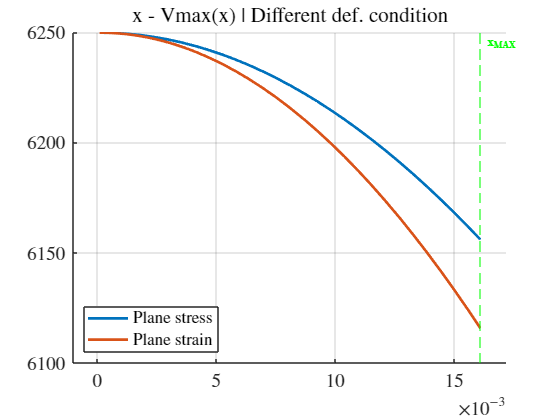

Vmax_pstress = sdata1(Vmax_pstress, strpstress);
Vmax_pstrain = sdata1(Vmax_pstrain, strpstrain);
myfig(1,"x - Vmax(x)"); clf; hold on
fplot(x, Vmax_pstress, x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, Vmax_pstrain, x_minmax, 'LineWidth',2, 'DisplayName', 'Plane strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','southwest')
title("x - Vmax(x) | Different def. condition")
xlim("padded")

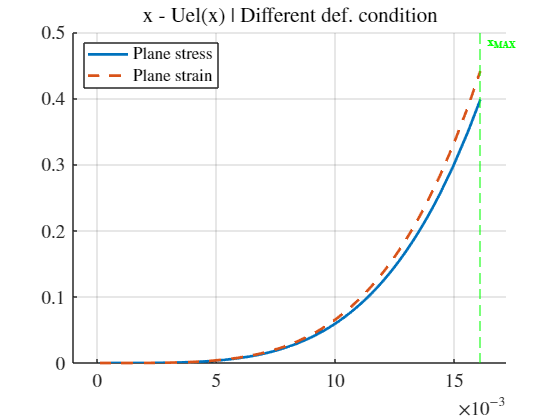

% Uel(x): Plane stress - Plane strain
tmpUel = 2 * 1 / 2 * (sigma_1 * epsilon_1) * [pstress.w * pstress.t_p, pstrain.w * pstrain.t_p] * pstress.l;
Uel_pstress = sdata1(pickelem(tmpUel(x),1), strpstress);
Uel_pstrain = sdata1(pickelem(tmpUel(x),2), strpstrain);
myfig(1,"x - Uel(x)"); clf; hold on;
fplot(x, Uel_pstress, x_minmax, 'LineWidth',2, 'DisplayName', 'Plane stress')
fplot(x, Uel_pstrain, x_minmax, '--', 'LineWidth',2, 'DisplayName', 'Plane strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','northwest')
title("x - Uel(x) | Different def. condition")
xlim("padded")

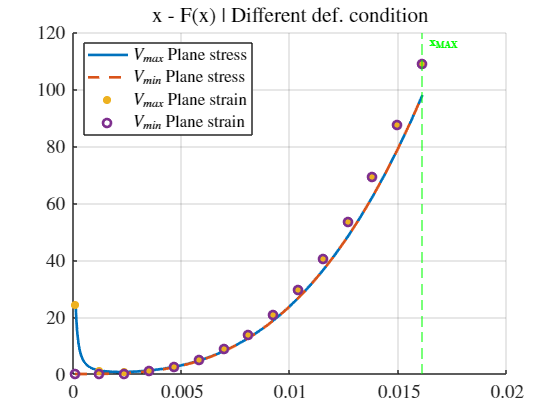

% F(x,v)
F_pstress = sdata1(diff(Uel_pstress, x) - V^2 /2 * diff(pstress.C,x), strpstress);
F_pstrain = sdata1(diff(Uel_pstrain, x) - V^2 /2 * diff(pstrain.C,x), strpstrain);

FVmax_pstress = subs(F_pstress, V, Vmax_pstress);
FVmin_pstress = subs(F_pstress, V, 0);
FVmax_pstrain = subs(F_pstrain, V, Vmax_pstrain);
FVmin_pstrain = subs(F_pstrain, V, 0);

myfig(1,"x - F(x)"); clf; hold on;
fplot(x, FVmax_pstress, x_minmax, 'LineWidth',2, 'DisplayName', '$V_{max}$ Plane stress')
fplot(x, FVmin_pstress, x_minmax, '--', 'LineWidth',2, 'DisplayName', '$V_{min}$ Plane stress')
fplot(x, FVmax_pstrain, x_minmax, '*', 'LineWidth',2, 'DisplayName', '$V_{max}$ Plane strain')
fplot(x, FVmin_pstrain, x_minmax, 'o','LineWidth',2, 'DisplayName', '$V_{min}$ Plane strain')
myxline(double(x_max), "x_{MAX}");
legend('FontWeight','bold', 'Location','northwest')
title("x - F(x) | Different def. condition")

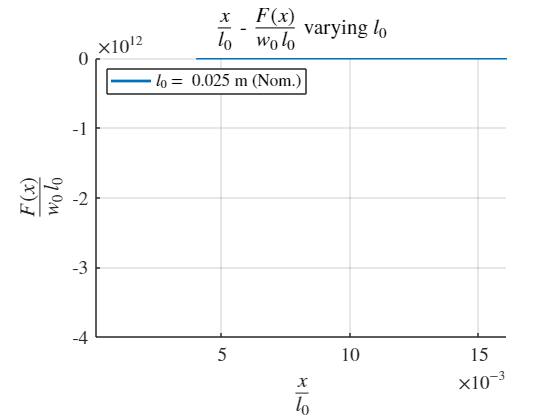

% Energy density for plane strain
l0_range = double(sdata1(l_0) - 0*0.9*sdata1(l_0) : 0.3*sdata1(l_0) : sdata1(l_0) + 0.9*sdata1(l_0));
Uel_pstrain = sdata1(pickelem(tmpUel(x),2), strpstrain, 'none');
F_pstrain = sdata1(diff(Uel_pstrain, x) - V^2 /2 * diff(pstrain.C,x), strpstrain, 'none');
F_pstrain = subs(sdata1(F_pstrain, 'except', [l_0, xi_0]), {l_0, V}, {l0_range, 0 * Vmax_pstrain / 2});

myfig(4, "x - F(x) varying $l_0$"); hold on
for i = 1:1%length(l0_range)
    if l0_range(i) == double(sdata1(l_0))
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m (Nom.)"]);
    else
        name = strjoin(["$l_0 =$", string(vpa(l0_range(i),4)), "m"]);
    end
    
    fplot(x / l0_range(i) , pickelem(F_pstrain(x / l0_range(i)), i) / double(sdata1(w_0 * tp_0)), x_minmax, 'LineWidth',2, 'DisplayName', name)
end
% myxline(double(x_max) , "x_{MAX}");
legend('FontWeight','bold', 'Location','northwest')
title("$\frac{x}{l_0}$ - $\frac{F(x)}{w_0 \, l_0}$ varying $l_0$")
xlabel("$\frac{x}{l_0}$")
ylabel("$\frac{F(x)}{w_0 \, l_0}$")

xlim(x_minmax)